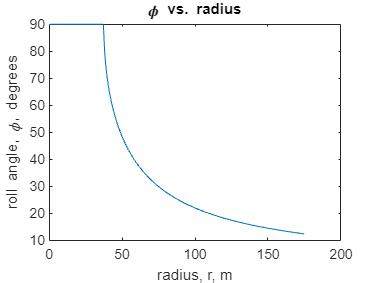

clear all; close all; clc;

e = .9;
r = 0:175; % Turn radius m
A = 22.82;%linspace(10,60,length(r)); % Aspect Ratio
rho = 1.0834; % Density at a+*lt
%[~, ~, ~, rho] = atmosisa(convlength(3000, 'ft', 'm'));

%W2S = 450;%linspace(250:550,length(r)); % Wing Loading N/m^2
W2S = 280; % to mathc figure 89 of Thomas
%W2S = 450 % messing with wing loading

L_Dmax = 22.82;

g = 9.81; % acceleration due to gravity (m/s)

C_L_max = (pi * A * e) / (2 * L_Dmax); % Maximum lift coefficient
%C_L_max = 2.7; % forced C_L max for debugging: maximum imaginable C_L_max

C_D_max = 2 * (C_L_max^2)/(pi * A * e); % Maximum drag coefficient
C_D_0 = C_D_max / 2; % Parasite drag coefficient

% Thermal updraft velocity
V_T = HorstmannThermal(r); % verticle speed of air in thermal (m/s)

% Sink rate in a turn of radius r
V_sc = SinkRateCircle(C_L_max, C_D_0, A, e, W2S, rho, r);

% plot phi as a function of radius
phi = acos(real(sqrt(1 - (2*W2S./(rho*r*g*C_L_max)).^2)));
plot(r, rad2deg(phi)); title("\phi vs. radius",Interpreter="tex"); xlabel("radius, r, m",Interpreter="tex"); ylabel("roll angle, \phi, degrees",Interpreter="tex");

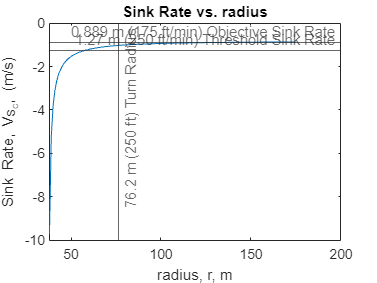


% plot sink rate 
plot(r, -V_sc); title("Sink Rate vs. radius",Interpreter="tex"); xlabel("radius, r, m",Interpreter="tex"); ylabel("Sink Rate, V_{S_C}, (m/s)",Interpreter="tex");
% add to plot mission constraints constraints
xline(76.2, "-","76.2 m (250 ft) Turn Radius") 
yline(-1.27, "-","1.27 m (250 ft/min) Threshold Sink Rate")
yline(-0.889, "-","0.889 m (175 ft/min) Objective Sink Rate")



% compute climb speed from thermal updraft speed and aircraft sink rate
V_c = V_T - V_sc; % climb speed (m/s)

% plot climb speed versus radius
plot(r, V_c);  title("Climb Rate vs. radius",Interpreter="tex"); xlabel("radius, r, m",Interpreter="tex"); ylabel("Climb Rate, V_C, (m/s)",Interpreter="tex");

% % add angle lines to the plot
% n_plotAngles = 6; % how many angle lines to add
% anglePlot_indices = ceil(linspace(1, length(r), n_plotAngles)); % uniformly diribute them
% for i = 1:length(anglePlot_indices)
%     anglePlot_index = anglePlot_indices(i);
%     xline(r(anglePlot_index), "--", sprintf("\\phi = %.2g", rad2deg(phi(anglePlot_index))), Interpreter="tex");
% end

% compute optimal turn radii
[V_C_max, maxIndex] = max(V_c,[],2);
V_C_max

V_C_max =     0.5509
    2.3280
    0.6544
    2.3743


r_opt = r(maxIndex)

r_opt =     57    55    83    77


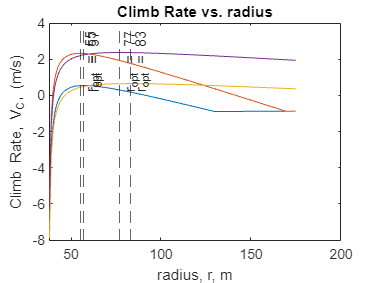


for i = 1:length(r_opt)
    xline(r_opt(i), "--", sprintf("r_{opt} = %.2g", r_opt(i)), Interpreter="tex");
end

## Cross-country speed in a Horstman thermal

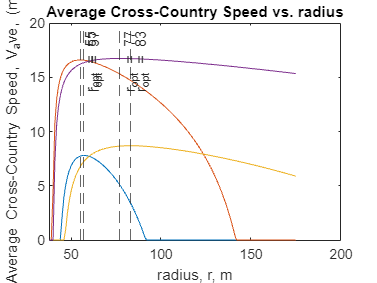


% Compute optimal interthermal glide lift coefficient
C_L = arrayfun(@(V_climb) LiftCoefficient_Optimal_Interthermal_Glide(C_D_0, A, e, rho, W2S, V_climb), V_c);


%V_avg = Vavgfsd(V_c, C_D_0, A, e, rho, W2S, C_L);
% these are not equal which is conserning
V_avg = AverageCrossCountrySpeed(V_c, C_D_0, A, e, rho, W2S, C_L);

plot(r,V_avg); title("Average Cross-Country Speed vs. radius",Interpreter="tex"); xlabel("radius, r, m",Interpreter="tex"); ylabel("Average Cross-Country Speed, V_ave, (m/s)",Interpreter="tex");

% plot the optimal radius to thermal
for i = 1:length(r_opt)
    xline(r_opt(i), "--", sprintf("r_{opt} = %.2g", r_opt(i)), Interpreter="tex");
end


V_ave_max = max(V_avg(:, maxIndex),[],2)

V_ave_max =     7.8030
   16.6052
    8.6968
   16.7446


phh_max = phi(maxIndex)

phh_max =     0.7127    0.7446    0.4657    0.5053


## Cross Country Speed Using the Quast Weather Model

% work out the appropriate way to weight the average
V_ave_horst = AverageCrossCountrySpeed_Horstmnan(e, A, C_D_0, W2S, rho, C_L_max)

V_ave_horst =     7.8037
   16.6052
    8.6968
   16.7446


V_ave_quast = dot(V_ave_horst, [.08,.42,.08,.42])

V_ave_quast = 15.3270